# Frequency Response Function Estimate

clear; clc; clear all; %clear all variables from the workspace
%frfest.m
%Birdsong June 2024
%Read experimental data file and overlay estimated TF frequency response plots


## load data

load 'bodedata.mat' %loads the experimental frequency response data file 

## parameters

format shortG
wp1 = 2.5;
wp2 = 4.5;

mp1 = 10;
mp2 = 1.778;

zeta1 = .06;
zeta2 = .14;

wn1 = wp1/sqrt(1-2*zeta1^2)

wn1 =         2.509


wn2 = wp2/sqrt(1-2*zeta2^2)

wn2 =        4.5909


## 4th order CE

% first 2nd Order CE
CE1 = [1, 2*zeta1*wn1, wn1^2]

CE1 =             1      0.30109       6.2953


% second 2nd Order CE
CE2 = [1, 2*zeta2*wn2, wn2^2]

CE2 =             1       1.2854       21.076


% combined 
num = [10*(wn1^2)*(wn2^2)] %define the numerator

num =        1326.8


den = conv(CE2, CE1) %define the denominator 

den =             1       1.5865       27.759       14.438       132.68


## define your estimated open-loop tranfer function here using the TF command

gp=tf(num,den)

gp =
 
                      1327
  ---------------------------------------------
  s^4 + 1.587 s^3 + 27.76 s^2 + 14.44 s + 132.7
 
Continuous-time transfer function.
Model Properties


P = pole(gp)

P =      -0.64272 +     4.5457i
     -0.64272 -     4.5457i
     -0.15054 +     2.5045i
     -0.15054 -     2.5045i


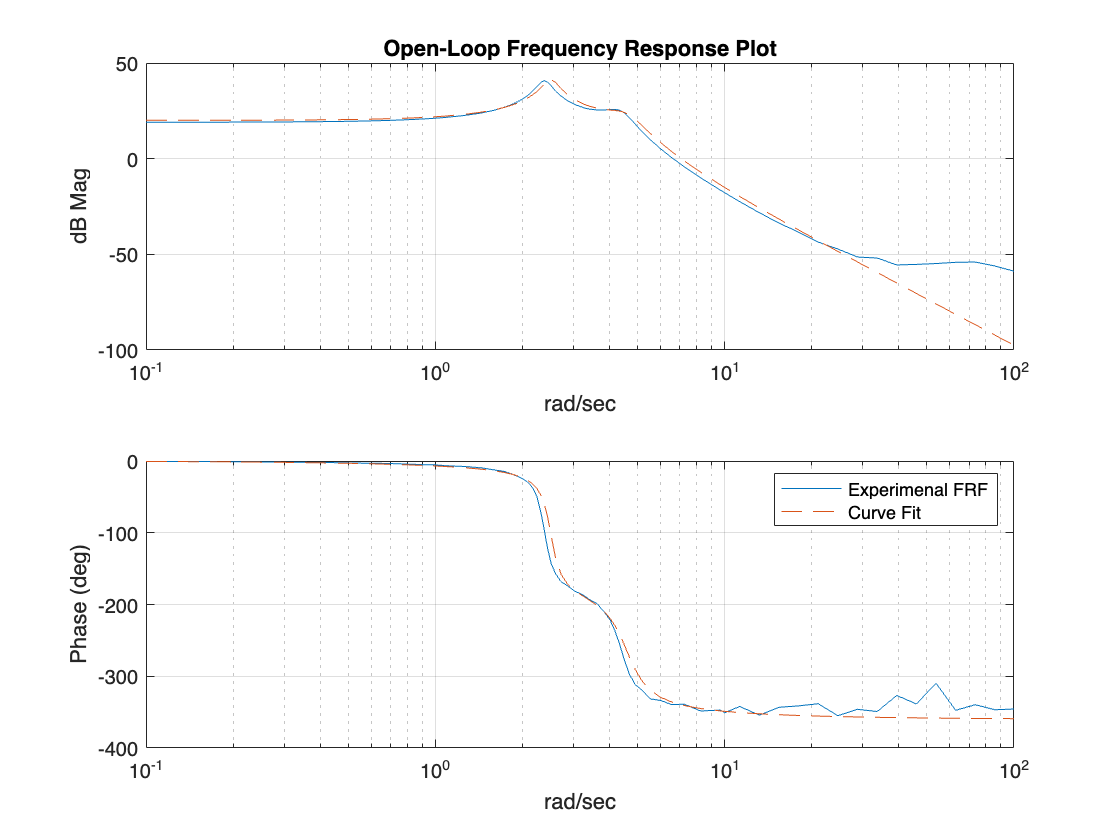

figure()
[mmod2,pmod2]=bode(gp,wout);%compute freq resp with w (rad/s) 

%plot the bode diagram
figure(1);subplot(211)
semilogx(wout,20*log10(magdata),wout,20*log10(squeeze(mmod2)),'--');
grid;xlabel('rad/sec');ylabel('dB Mag');
title('Open-Loop Frequency Response Plot');
subplot(212);
semilogx(wout,phasedata,wout,squeeze(pmod2),'--'); 
xlabel('rad/sec');ylabel('Phase (deg)');grid
legend('Experimenal FRF','Curve Fit')

[A B C D] = tf2ss(num,den);
Step = ss(A,B,C,D)

Step =
 
  A = 
           x1      x2      x3      x4
   x1  -1.587  -27.76  -14.44  -132.7
   x2       1       0       0       0
   x3       0       1       0       0
   x4       0       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
         x1    x2    x3    x4
   y1     0     0     0  1327
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


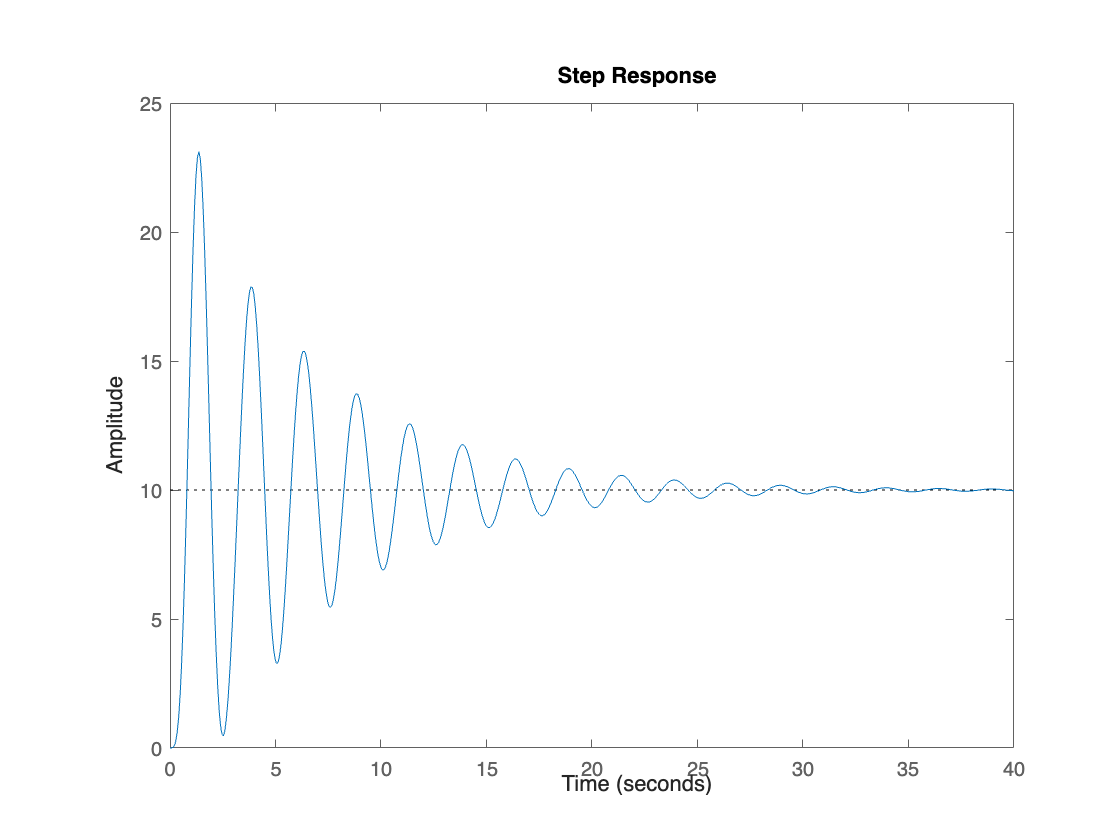

figure()
step(Step)

% RL tool

% rltool(gp)

%full state feedback controller
Ts = 0.2;
wn3 = 2.5;
zeta3 = 20/wn3;
wn4 = 4.5;
zeta4 = 20/wn4;

wd3 = wn3*sqrt(1-zeta3^2)

wd3 =             0 +     19.843i


wd4 = wn4*sqrt(1-zeta4^2)

wd4 =             0 +     19.487i


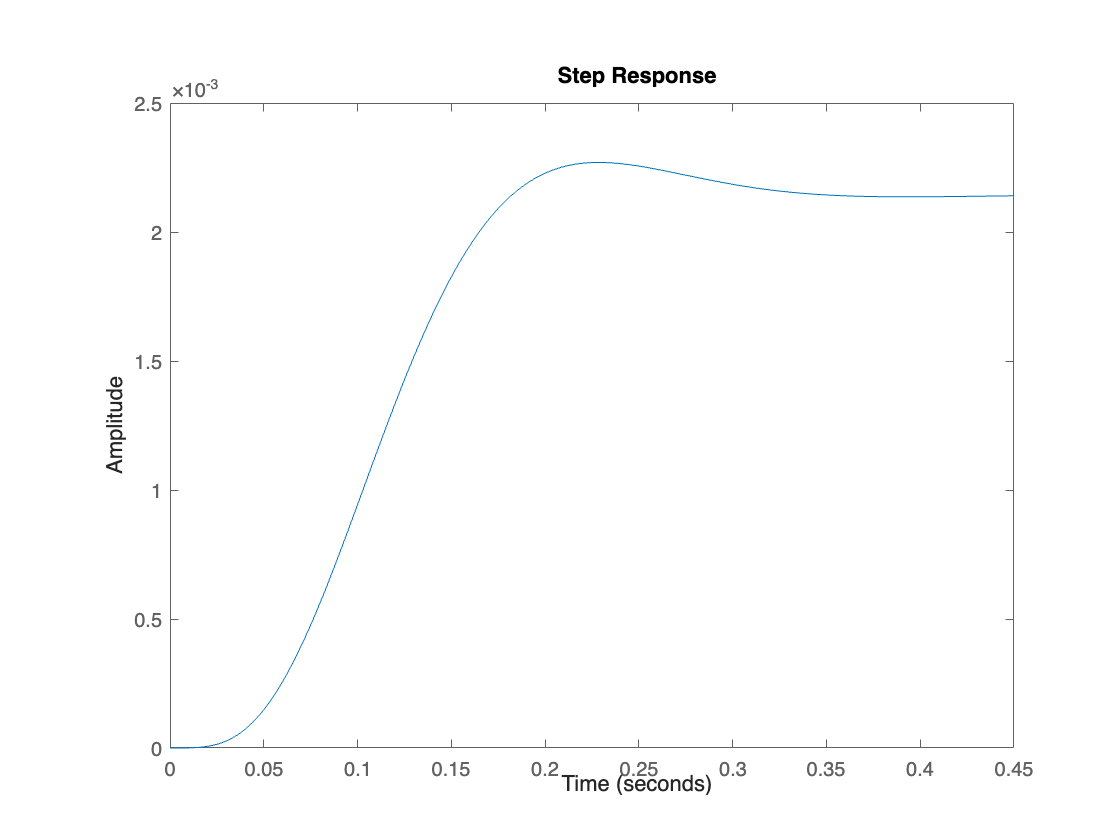

new_poles = [-20+wd3, -20-wd3, -20+wd4, -20-wd4];
%new_poles = [-0.65+2.5i,-0.65-2.5i, -2+3i, -2-3i]
K = place(A,B,new_poles) ;
a_cl = A-B*K;
clsys = ss(a_cl,B,C,D) ;
step(clsys)

%LQR
w = 1;
Q = [w 0 0 0;
     0 5000*w 0 0;
     0 0 w 0;
     0 0 0 5000];
R = [1];
[Klqr, S, P]= lqr(A, B, Q, R)

Klqr =        10.222       67.962       132.62       17.666


S =        10.222       67.962       132.62       17.666
       67.962       953.66         1696       1564.9
       132.62         1696        12111        10708
       17.666       1564.9        10708        20194


P =       -0.8263 +      1.127i
      -0.8263 -      1.127i
       -5.078 +     7.1553i
       -5.078 -     7.1553i


sys1 = ss(A-B*Klqr,B,C,D);
sys1

sys1 =
 
  A = 
           x1      x2      x3      x4
   x1  -11.81  -95.72  -147.1  -150.3
   x2       1       0       0       0
   x3       0       1       0       0
   x4       0       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
         x1    x2    x3    x4
   y1     0     0     0  1327
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


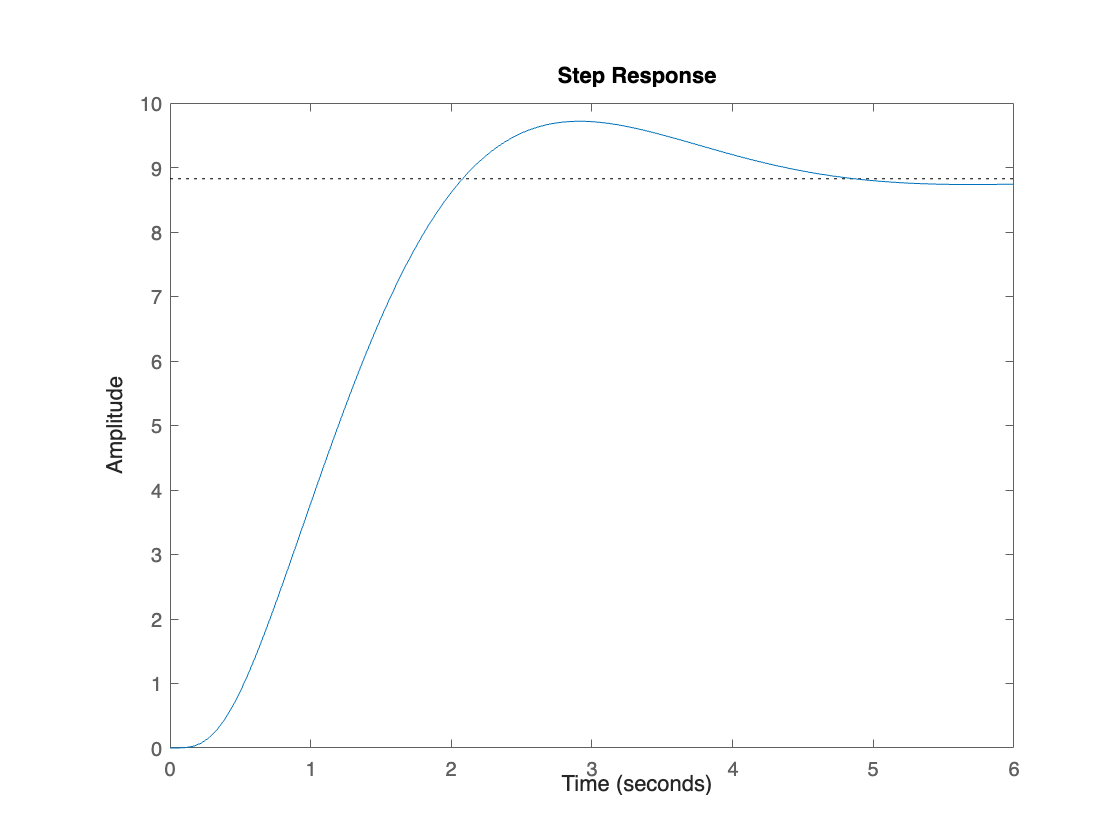

figure()
step(sys1)